## **ALS Mid-Term Project**

submitted by** : Karthik Balaji Keshavamurthi**

### **Problem 1. State Space Formulation:**

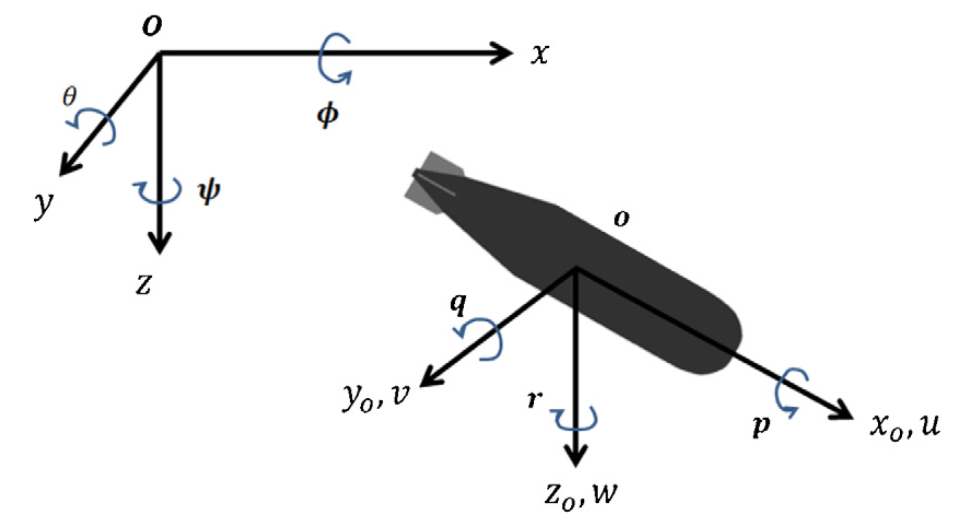

**Equations of motion:**

To obtain the Dynamic equations of motion, we analyze all the forces and moments on the submarine at respective directions and then use Newton's Second law to obtain the following equations.

$\left(m+X_{\dot{u} } \right)\ddot{x} \;\;=\;-X_u \;\dot{x} \;\;\;+X_T \;\;$                                                        (1)

$\left(m+Z_{\dot{w} } \right)\ddot{z} \;\;=\;\;-Z_{\dot{q} } \;\theta^¨ \;\;-Z_w \;\dot{z} \;+Z_q \;\theta^˙ \;+Z_s \;+Z_b$                            (2)

$\left(I_y \;+M_{\dot{q} } \right)\theta^¨ =\;\;-M_{\dot{w} } \;\ddot{z} -M_q \;\theta^˙ \;-M_w \;\;\theta^˙ \;-x_{s\;} \;Z_s \;-x_b \;Z_b \;\;\;\;$              (3)

where the constants are:

$X_{\dot{u} }$ is the 𝑥(-direction “added mass” from accelerating water (kg)

$X_u$ is the 𝑥(-direction hydrodynamic “drag” coefficient (N•s/m)

$Z_{\dot{w} }$ is the 𝑧(-direction “added mass” from accelerating water (kg)

$Z_w$ is the 𝑧(-direction hydrodynamic “drag” coefficient (N•s/m)

$Z_{\dot{q} }$ is the 𝑧(-direction “added mass” caused by rotation (kg•m)

$Z_q$ is the 𝑧(-direction hydrodynamic drag caused by rotation (kg•m/s)

$M_{\dot{q} }$ is the “added rotational inertia” about the 𝑦(-axis (kg•m2)

$M_q$ is the moment “drag” coefficient about the 𝑦(-axis (N•m•s)

$M_{\dot{w} }$ is the “added rotational inertia” about the 𝑦(-axis (kg•m)

$M_w$ is the moment “drag” coefficient about the 𝑦(-axis (N•s)

$x_s$ is the position of the stern (rear) control surface in the 𝑥(-direction (m)

$x_b$ is the position of the bow (front) control surface in the 𝑥(-direction (m)

**Inputs:**

The inputs to the system are the following:

- $X_{T\;}$- the thurst in the $x_0$ direction in newton.

- $Z_s$ - the stern thrust in the $z_o$direction in newton

- $Z_b$ - the blow thrust in the $z_0$direction in newton

The Constraint to the input is that the magnitude must never be more than 3 x ${10}^6 \;N$.

**Outputs:**

The outputs that we measure using our sensors are the following:

- $\theta$ - The pitch angle in radians

- z  - The depth in meters

- x  - The position in meters

**State Variables:**

To construct the state space equation, the following is my choice of state variables.


$$\begin{array}{l}
x_1 \;\;=\dot{x} \\
x_{2\;} \;=x\\
x_{3\;} \;=\dot{z} \\
x_{4\;} \;=z\\
x_5 \;=\theta^˙ \\
x_6 \;=\theta 
\end{array}$$


Using these state variables, we rearrange the Equations of motion to get the state and output equations. 

**State Equations:**

$\dot{x_1 } \;=\left\lbrack \frac{-X_u }{\left(m+X_{\dot{u} } \right)}\right\rbrack \;\ldotp x_1 \;\;\;+\left\lbrack \frac{1}{\left(m+X_{\dot{u} } \right)}\right\rbrack \ldotp X_T$                                                                      (4)

$\dot{x_2 } ={\;\;x}_1$                                                                                                                         (5)

$\begin{array}{l}
\dot{x_3 } =\left\lbrack \frac{\left(I_y \;Z_w \;+M_{\dot{q} } \;Z_w -M_w \;Z_{\dot{q} } \right)}{\xi }\right\rbrack x_3 \;+\left\lbrack \frac{\left(I_y {\;Z}_q +M_{\dot{q} } \;Z_q -M_q \;Z_{\dot{q} } \right)}{\xi }\right\rbrack \;x_5 \;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left\lbrack \frac{\left(-I_y -M_{\dot{q} } -Z_{\dot{q} } \;x_s \right)}{\xi }\right\rbrack \;Z_s \;+\left\lbrack \frac{\left(-I_y -M_{\dot{q} } -Z_{\dot{q} } \;x_b \right)}{\xi }\right\rbrack Z_b 
\end{array}$            (6)

$\dot{x_4 } =x_3$                                                                                                                          (7)

$\begin{array}{l}
\dot{x_5 } =\left\lbrack \frac{-\left(m+Z_{\dot{w} } \right)\left(I_y \;Z_w \;+M_{\dot{q} } \;Z_w -M_w \;Z_{\dot{q} } \right)\;-Z_w \xi }{Z_{\dot{q} } \xi }\right\rbrack x_3 +\\
\;\;\;\;\;\;\;\;\;\;\left\lbrack \frac{-\left(m+Z_{\dot{w} } \right)\left(I_y \;Z_q \;+M_{\dot{q} } \;Z_q -M_q \;Z_{\dot{q} } \right)\;-Z_q \xi }{Z_{\dot{q} } \xi }\right\rbrack x_5 \;\;+\\
\;\;\;\;\;\;\;\;\;\left\lbrack \frac{\left(I_y +M_{\dot{q} } +Z_{\dot{q} } \;x_s \right)\left(m+Z_{\dot{w} } \right)+\xi }{Z_{\dot{q} } \xi }\right\rbrack Z_s +\left\lbrack \frac{\left(I_y +M_{\dot{q} } +Z_{\dot{q} } \;x_b \right)\left(m+Z_{\dot{w} } \right)+\xi }{Z_{\dot{q} } \xi }\right\rbrack Z_b \;\;\;
\end{array}$          (8)

$\dot{x_6 } =x_5$                                                                                                                          (9)

where,


$$\xi \;=M_{\dot{w} } \;Z_{\dot{q} } -m\;I_y -m\;M_{\dot{q} } -Z_{\dot{w} } I_y -\;M_{\dot{q} } Z_{\dot{w} }$$


**Output Equations:**

The output equations are:

$x=x_2$                                                                                                                            (10)

$z=x_4$                                                                                                                            (11)

$\theta =x_6$                                                                                                                            (12)

clear 
close all
clc

## State Space Formulation


% I have used Alphabets to denote terms for simplicity during derivation of
% the State Space Equations.
syms A B C D E F G H J K XS XB XT ZS ZB M IY EPS
syms Xudot Xu Zwdot Zw Zqdot Zq Mqdot Mq Mwdot Mw Xs Xb XT Zs Zb m

EPS = J*E - M*IY - M*G - C*IY - G*C;
A1 = [(-B/(M+A)) 0 0 0 0 0
       1 0 0 0 0 0
       0 0 ((IY*D + G*D - K*E)/EPS) 0 ((IY*F + G*F - H*E)/EPS) 0
       0 0 1 0 0 0
       0 0 (-((M+C)/E)*((IY*D + G*D - K*E)/EPS) - (D/E)) 0 (-((M+C)/E)*((IY*F + G*F - H*E)/EPS) - (F/E)) 0
       0 0 0 0 1 0];
A1 = subs(A1,[A,B,C,D,E,F,G,H,J,K,M],[Xudot,Xu,Zwdot,Zw,Zqdot,Zq,Mqdot,Mq,Mwdot,Mw,m])

$$A1 = \begin{array}{l} \left(\begin{array}{cccccc} -\frac{\mathrm{Xu}}{\mathrm{Xudot}+m} & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{\sigma_{2}}{\sigma_{1}} & 0 & -\frac{\sigma_{3}}{\sigma_{1}} & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & \frac{\left(\mathrm{Zwdot}+m\right)\,\sigma_{2}}{\mathrm{Zqdot}\,\sigma_{1}}-\frac{\mathrm{Zw}}{\mathrm{Zqdot}} & 0 & \frac{\left(\mathrm{Zwdot}+m\right)\,\sigma_{3}}{\mathrm{Zqdot}\,\sigma_{1}}-\frac{\mathrm{Zq}}{\mathrm{Zqdot}} & 0\\ 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{IY}\,\mathrm{Zwdot}+\mathrm{Mqdot}\,\mathrm{Zwdot}-\mathrm{Mwdot}\,\mathrm{Zqdot}+\mathrm{IY}\,m+\mathrm{Mqdot}\,m\\ \sigma_{2}=\mathrm{IY}\,\mathrm{Zw}+\mathrm{Mqdot}\,\mathrm{Zw}-\mathrm{Mw}\,\mathrm{Zqdot}\\ \sigma_{3}=\mathrm{IY}\,\mathrm{Zq}-\mathrm{Mq}\,\mathrm{Zqdot}+\mathrm{Mqdot}\,\mathrm{Zq} \end{array}$$

   
B1 = [(1/(M+A)) 0 0
       0 0 0
       0 ((-IY - G - E*Xs)/EPS) ((-IY - G - E*Xb)/EPS)
       0 0 0
       0 (((IY+G+E*Xs)*(M+C) + EPS)/(EPS*E)) (((IY+G+E*Xb)*(M+C) + EPS)/(EPS*E))
       0 0 0];

B1 = subs(B1,[A,B,C,D,E,F,G,H,J,K,M],[Xudot,Xu,Zwdot,Zw,Zqdot,Zq,Mqdot,Mq,Mwdot,Mw,m])

$$B1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{1}{\mathrm{Xudot}+m} & 0 & 0\\ 0 & 0 & 0\\ 0 & \frac{\sigma_{2}}{\sigma_{1}} & \frac{\sigma_{3}}{\sigma_{1}}\\ 0 & 0 & 0\\ 0 & \frac{\mathrm{IY}\,\mathrm{Zwdot}+\mathrm{Mqdot}\,\mathrm{Zwdot}-\mathrm{Mwdot}\,\mathrm{Zqdot}+\mathrm{IY}\,m+\mathrm{Mqdot}\,m-\left(\mathrm{Zwdot}+m\right)\,\sigma_{2}}{\mathrm{Zqdot}\,\sigma_{1}} & \frac{\mathrm{IY}\,\mathrm{Zwdot}+\mathrm{Mqdot}\,\mathrm{Zwdot}-\mathrm{Mwdot}\,\mathrm{Zqdot}+\mathrm{IY}\,m+\mathrm{Mqdot}\,m-\left(\mathrm{Zwdot}+m\right)\,\sigma_{3}}{\mathrm{Zqdot}\,\sigma_{1}}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{IY}\,\mathrm{Zwdot}+\mathrm{Mqdot}\,\mathrm{Zwdot}-\mathrm{Mwdot}\,\mathrm{Zqdot}+\mathrm{IY}\,m+\mathrm{Mqdot}\,m\\ \sigma_{2}=\mathrm{IY}+\mathrm{Mqdot}+\mathrm{Xs}\,\mathrm{Zqdot}\\ \sigma_{3}=\mathrm{IY}+\mathrm{Mqdot}+\mathrm{Xb}\,\mathrm{Zqdot} \end{array}$$

C1 = [0 1 0 0 0 0 
      0 0 0 1 0 0
      0 0 0 0 0 1]

C1 =      0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1


  D1 = zeros(3)

D1 =      0     0     0
     0     0     0
     0     0     0


## Problem 2. Calculation of Parameters

% Let us update values for the constants
mass = 500;                           % in kg
L = 25;                            % in m
Iy = (1/300) * mass * (L^2);          % in kg m^2
X_udot = mass/30;                      % in kg
X_u = 94;                           % in N s/m
Z_wdot = (mass/10);                    % in kg
Z_w = 4.7e2;                        % in N s/m
Z_qdot = mass/20;                      % in kg m
Z_q = 9.5e2;                        % in kg m/s
M_qdot = Iy/20;                     % in kg m^2
M_q = 1.1e3;                        % in N m s
M_wdot = Iy/40;                     % in kg m 
M_w = 320;                          % in N s
xs = -L/3;                         % in m
xb = L/3;                          % in m
Umax = 3e6;                        % in N


## Problem 3. State Space Representation of System:

A_matrix = double(subs(A1,[Xudot,Xu,Zwdot,Zw,Zqdot,Zq,Mqdot,Mq,Mwdot,Mw,m,IY],[X_udot,X_u,Z_wdot,Z_w,Z_qdot,Z_q,M_qdot,M_q,M_wdot,M_w,mass,Iy]))

A_matrix =    -0.1819         0         0         0         0         0
    1.0000         0         0         0         0         0
         0         0   -0.8422         0   -1.6834         0
         0         0    1.0000         0         0         0
         0         0   -0.2725         0   -0.9656         0
         0         0         0         0    1.0000         0


B_matrix = double(subs(B1,[Xudot,Xu,Zwdot,Zw,Zqdot,Zq,Mqdot,Mq,Mwdot,Mw,m,IY,Xs,Xb],[X_udot,X_u,Z_wdot,Z_w,Z_qdot,Z_q,M_qdot,M_q,M_wdot,M_w,mass,Iy,xs,xb]))

B_matrix =     0.0019         0         0
         0         0         0
         0    0.0015    0.0022
         0         0         0
         0    0.0076   -0.0077
         0         0         0


C_matrix = C1

C_matrix =      0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1


D_matrix = D1

D_matrix =      0     0     0
     0     0     0
     0     0     0


Now, we will have to describe the parameters of the LTI object using the SET command. To do this, first we create the LTI object using our

State space Matrices.

% Let us first create the LTI Object
original_system = ss(A_matrix,B_matrix,C_matrix,D_matrix);
set(original_system,'StateName',{'x-Velocity','x-Position','z-Velocity','z-Position','Pitch Rate','Pitch Angle'});
set(original_system,'StateUnit',{'m/s','m','m/s','m','rad/s','rad'});
set(original_system,'InputName',{'Surge Thrust','Stern Thrust','Bow Thrust'})
set(original_system,'InputUnit',{'N','N','N'})
set(original_system,'OutputName',{'Position-x','Depth-z','Pitch Angle'})
set(original_system,'OutputUnit',{'m','m','rad'})

## Problem 4: Check for Minimum Realization:

To check for Minimum Realization, we use the matlab minreal function for checking for the minimum realisation.

From the Documentation, we can see that the minreal function filters out any redundant states and provides the least realization. 

If the object returned due to this function is similar to the original LTI object, our system is a minimum realization system.


Minimum_Realisation = minreal(original_system)


Minimum_Realisation =
 
  A = 
                 x-Velocity   x-Position   z-Velocity   z-Position   Pitch Rate  Pitch Angle
   x-Velocity       -0.1819            0            0            0            0            0
   x-Position             1            0            0            0            0            0
   z-Velocity             0            0      -0.8422            0       -1.683            0
   z-Position             0            0            1            0            0            0
   Pitch Rate             0            0      -0.2725            0      -0.9656            0
   Pitch Angle            0            0            0            0            1            0
 
  B = 
                Surge Thrust  Stern Thrust    Bow Thrust
   x-Velocity       0.001935             0             0
   x-Position              0             0             0
   z-Velocity              0      0.001473      0.002167
   z-Position              0             0             0
   Pitch Rate          

From above, you can see the State space matrices are the same as our original_system's matrices. 

Hence, our State Space Model is a **Minimum Realization.**

## Problem 5: Determine Controllability:

We will have to find the Controllability matrix and check for its rank. I have made a conditional statement for this purpose.

Q =  ctrb(A_matrix,B_matrix);

if rank(Q) == size(A_matrix,1)
    % This means that Matrix is controllable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Controllable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Controllable')
end

Matrix is Completely Controllable


We can see from the output that the matrix is completely controllable. Now, we will check if any subset is completely controllable. 

To accomplish this, we will take two of the three columns of B matrix to check if any of the inputs are redundant. 

**Case 1: **Only XT and Zs are considered, i.e Columns 1 and 2 only

Q =  ctrb(A_matrix,B_matrix(:,1:2));

if rank(Q) == size(A_matrix,1)
    % This means that Matrix is controllable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Controllable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Controllable')
end

Matrix is not Completely Controllable


**Case 2: **Only Zs and Zb are considered, i.e Columns 2 and 3 only

Q =  ctrb(A_matrix,B_matrix(:,2:3));

if rank(Q) == size(A_matrix,1)
    % This means that Matrix is controllable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Controllable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Controllable')
end

Matrix is not Completely Controllable


**Case 3: **Only XT and Zb are considered, i.e Columns 1 and 3 only

Q =  ctrb(A_matrix,B_matrix(:,[1,3]));

if rank(Q) == size(A_matrix,1)
    % This means that Matrix is controllable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Controllable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Controllable')
end

Matrix is not Completely Controllable


From these three cases, we can clearly see that no subsets of the Control Inputs can make the system **Completely Controllable.**

## Problem 6: Compute Open Loop Poles:

We will use the damp function to obtain the Natural Frequency, Damping Ratios and Open loop poles.

Now, the Natual frequency values returned from this section will be in rad/s and we are asked to display in terms of Hz. 

Hence, we will also convert them to the required format and use the matlab Table function to show the results.

[natural_frequency, damping_ratios, open_loop_poles] =damp(original_system);
natural_frequency = natural_frequency * (1/(2*pi));
table(open_loop_poles,natural_frequency,damping_ratios,'VariableNames',{'Open Loop Poles', 'Natural Frequency in Hz', 'Damping Ratios'})

ans = 6×3 table
    Open Loop Poles    Natural Frequency in Hz    Damping Ratios
    _______________    _______________________    ______________

              0                      0                  -1      
              0                      0                  -1      
              0                      0                  -1      
       -0.18194               0.028956                   1      
       -0.22377               0.035615                   1      
         -1.584                 0.2521                   1      


## Problem 7: Initial Response:

We are given initial a set of initial conditions. Now, we will need to map the initial conditions from the inertial or global frame to the submarine's local frame. 

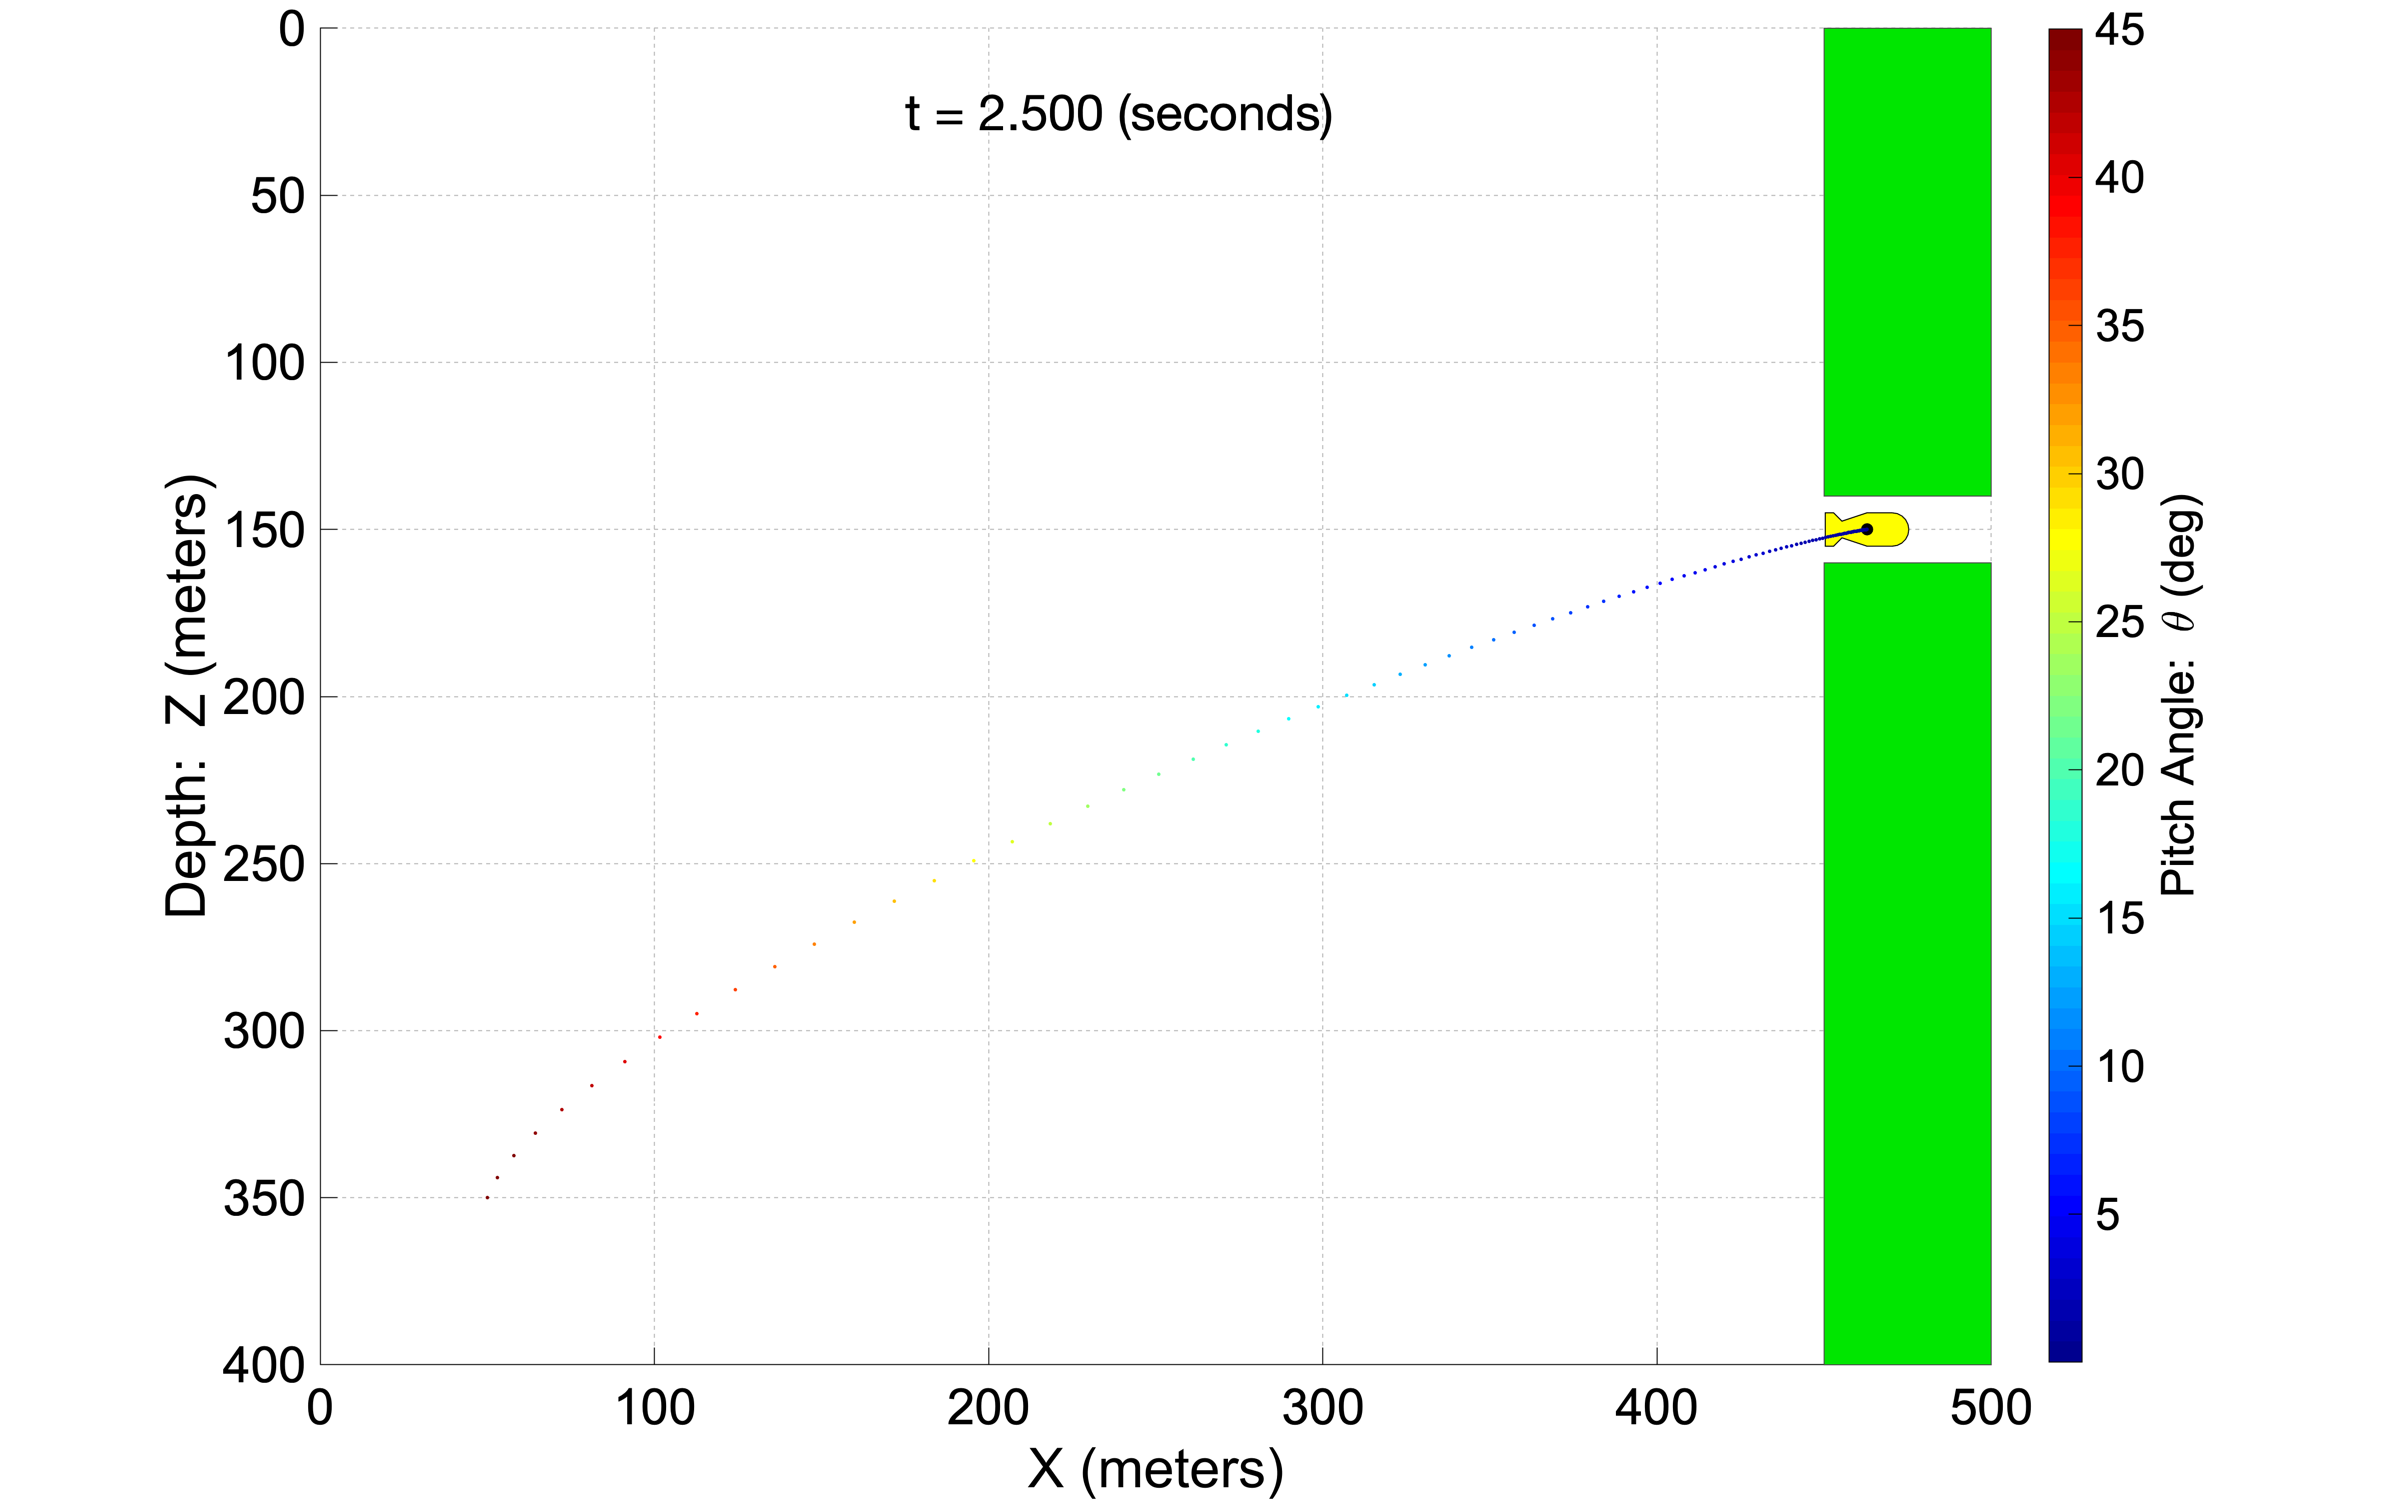

We can see that the difference in the x axis is 465 m  and z axis is 150 m. Hence, we convert x position from 50 to -415 and z from 350 to 200.

initial_condition_vector = [100,-415,-300,200,0,45*pi/180]';

We will use the matlab function 'inital' to get the response of the function in open loop and plot the response in a subplot. 

[open_loop_output, time, open_loop_state] = initial(original_system,initial_condition_vector);

Now we also have to find the settling time and place a marker on the response. 

For this we will first use the lsiminfo command to find the settling time and then place a marker. 

% The Default Settling Time for lsiminfo is 2%. To change it to 5%, we will
% need to add two extra arguments to lsiminfo other than output and time.
s = lsiminfo(open_loop_output,time,'SettlingTimeThreshold',0.05)

s = 3×1 struct array with fields:
    SettlingTime
    Min
    MinTime
    Max
    MaxTime


Here Fields 1,2 and 3 are the xPosition, z-Postition and Pitch angle outputs respectively.

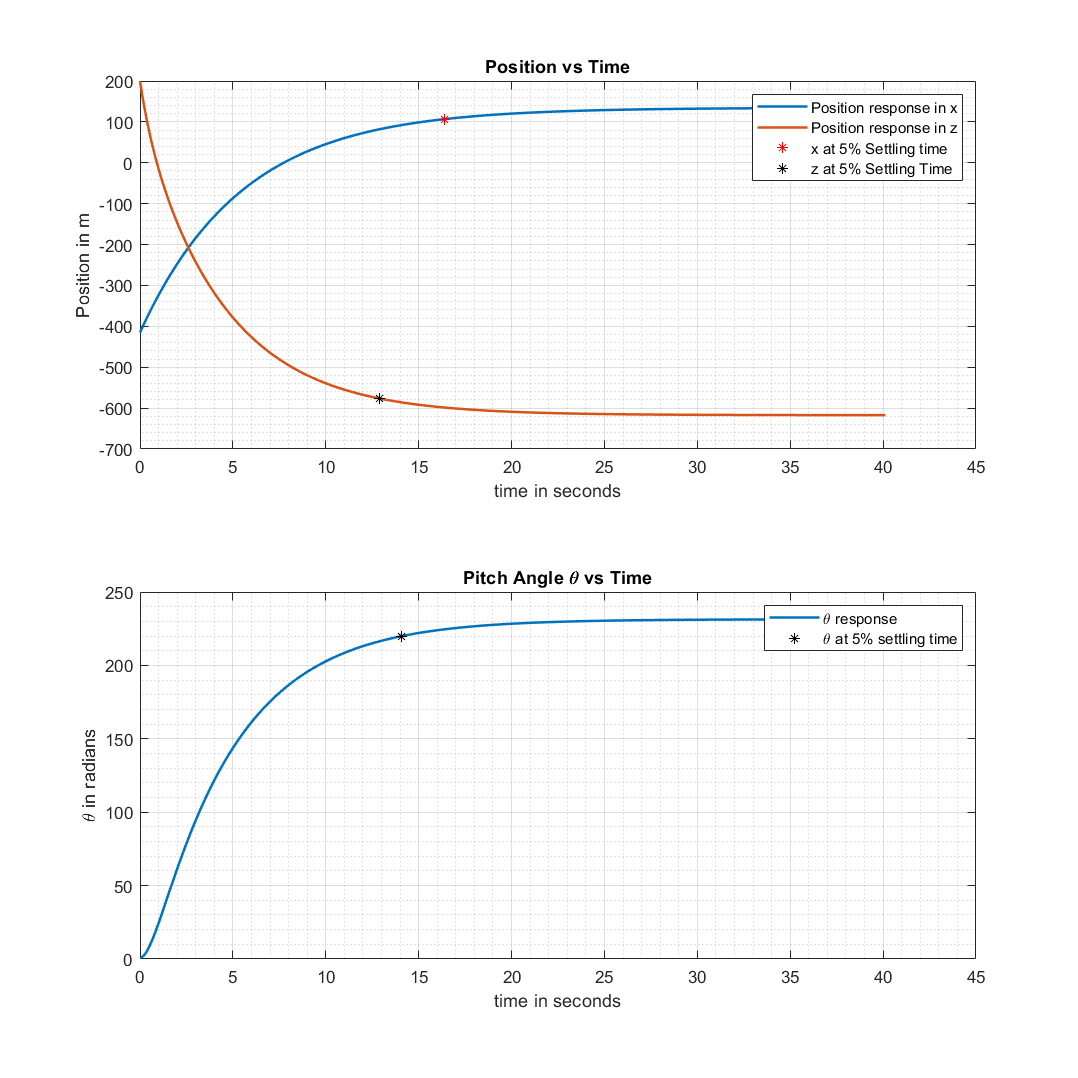


% Now we have the three settling times. To place a marker, we need to find
% the index of that specific time. 

[~,index_output1] = min(abs(time - s(1).SettlingTime));
[~,index_output2] = min(abs(time - s(2).SettlingTime));
[~,index_output3] = min(abs(time - s(3).SettlingTime));

% Now we plot the graphs. The x and z have the same units and hence will be
% plot in the same graph. 
figure('Position',[10,10,900,900])
subplot(2,1,1)

plot(time, open_loop_output(:,1:2),'linewidth',1.5)
title('Position vs Time')
grid on
grid minor
hold on
plot(time(index_output1,1),open_loop_output(index_output1,1),'r*')
hold on 
plot(time(index_output2,1),open_loop_output(index_output2,2),'k*')
xlabel('time in seconds')
ylabel('Position in m')
legend('Position response in x', 'Position response in z','x at 5% Settling time','z at 5% Settling Time')

subplot(2,1,2)
plot(time, open_loop_output(:,3),'linewidth',1.5)
hold on
grid on
grid minor
plot(time(index_output3,1),open_loop_output(index_output3,3),'k*')
title('Pitch Angle \theta vs Time')
legend('\theta response','\theta at 5% settling time')
xlabel('time in seconds')
ylabel('\theta in radians')

## Problem 8 - Full State Feedback Controller

Now we will start designing the full state feedback controller. To estimate the Gain Matrix, we will have to place the poles at locations which improve the system performance and also satisfy all the constraints of the system. 

As we know the constrains are:

- The submarine should enter the tunnel before 5 seconds.

- Its trajectory must be smooth and stable,i.e the vehicle must not spin off or fly off to locations before entering the tunnel. 

- The maximum magnitude of control input is 3 x ${10}^6 \;N$.

We have been given the animate_auv function to simulate the trajectory of the AUV in global coordinates.

Let us first see the trajectory of the Initial response. We should first tranform coordinates from Local frame to world coordinates before providing them as input to the animate_auv function.

pos_x = open_loop_output(:,1) + 465;
pos_z  = open_loop_output(:,2) + 150;
theta = open_loop_output(:,3);
%animate_auv(time,pos_x,pos_z,theta) 

It is evident that the open loop system fails to enter the tunnel. This lack of convergence is due to the three rigid body poles present in the system (poles with magnitude 0). Now, we will have to iterately place poles to satisfy all the constraints mentioned above. We will use the place function to accomplish this task and calculate the gain matrix. 

## Choice 1 : Arbitrary First Choice

closed_loop_poles = [-1,-1,-1,-1.5,-1.5,-1.5];
G = place(A_matrix,B_matrix,closed_loop_poles); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y1, t1, x1] = initial(new_sys,initial_condition_vector);
pos_x = y1(:,1)+465;
pos_z = y1(:,2)+150;
theta = y1(:,3);
input1 = -G*(x1');
maxinput1 = max(abs(input1(:)))

maxinput1 = 2.0186e+05

s = lsiminfo(y1,t1,'SettlingTimeThreshold',0.05);
settling_time = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
output_names = {'Position-x', 'Position-y','Pitch Angle'};
table(output_names',settling_time','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         3.7756     
    {'Position-y' }         1.9971     
    {'Pitch Angle'}         3.9402     


%animate_auv(t1,pos_x,pos_z,theta)

### Inference:

Here, the max input is lesser than the max allowable input and the submarine also enters the tunnel with a stable path. However, the time taken for the auv to enter the tunnel is high and can be reduced by increasing the control effort.

## Choice 2 - Increase Control Effort:

closed_loop_poles(2,:) = [-2,-2,-2,-2.5,-2.5,-2.5];
G = place(A_matrix,B_matrix,closed_loop_poles(2,:)); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y2, t2, x2] = initial(new_sys,initial_condition_vector);
pos_x = y2(:,1)+465;
pos_z = y2(:,2)+150;
theta = y2(:,3);
input2 = -G*(x2');
maxinput2 = max(abs(input2(:)))

maxinput2 = 8.4898e+05

s = lsiminfo(y2,t2,'SettlingTimeThreshold',0.05);
settling_time(2,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(2,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         2.0903     
    {'Position-y' }         1.7252     
    {'Pitch Angle'}         2.1403     


%animate_auv(t2,pos_x,pos_z,theta)

### Inference:

Here, the Submarine Does not enter the tunnel. Time taken to reach where the AUV reached seems fine. Control Effort is still within bounds.

The system seems to be over damped. Let us try to use complex conjugate pairs and decrease damping. 

## Choice 3: Complex Poles

closed_loop_poles(3,:) = [-2-2i,-2+2i,-2,-2.5-2.5i,-2.5+2.5i,-2.5];
G = place(A_matrix,B_matrix,closed_loop_poles(3,:)); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y3, t3, x3] = initial(new_sys,initial_condition_vector);
pos_x = y3(:,1)+465;
pos_z = y3(:,2)+150; 
theta = y3(:,3);
input3 = -G*(x3');
maxinput3 = max(abs(input3(:)))

maxinput3 = 1.2015e+06

s = lsiminfo(y3,t3,'SettlingTimeThreshold',0.05);
settling_time(3,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(3,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         1.3358     
    {'Position-y' }        0.76215     
    {'Pitch Angle'}         1.7811     


%animate_auv(t3,pos_x,pos_z,theta)

### Inference:

We can see that the AUV did not enter the tunnel again. However, the trajectory it took was unstable showing that a damping of 0.707 is too less for the 

dynamics of the system. We might have to increase the damping and will also simulataneusly increase the real poles values.

## Choice 4: Increase Damping

closed_loop_poles(4,:) = [-2+0.5i,-2-0.5i,-3.5,-2.5-0.5i,-2.5+0.5i,-3.8];
G = place(A_matrix,B_matrix,closed_loop_poles(4,:)); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y4, t4, x4] = initial(new_sys,initial_condition_vector);
pos_x = y4(:,1)+465;
pos_z = y4(:,2)+150;
theta = y4(:,3);
input4 = -G*(x4');
maxinput4 = max(abs(input4(:)))

maxinput4 = 9.7581e+05

s = lsiminfo(y4,t4,'SettlingTimeThreshold',0.05);
settling_time(4,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(4,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }          1.944     
    {'Position-y' }          2.184     
    {'Pitch Angle'}         3.0488     


%animate_auv(t4,pos_x,pos_z,theta)

### Inference:

The performance seems to have deteriorated as the auv spins throughout the trajectory and it still does not enter the poles. Even reduction of damping 

by a small margin causes the vehicle to spin. Hence I have decided to use only real poles for this system. 

## Choice 5: Larger Real Poles

closed_loop_poles(5,:) = [-3,-3,-3.2,-3.3,-2.9,-3.1];
G = place(A_matrix,B_matrix,closed_loop_poles(5,:)); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y5, t5, x5] = initial(new_sys,initial_condition_vector);
pos_x = y5(:,1)+465;
pos_z = y5(:,2)+150;
theta = y5(:,3);
input5 = -G*(x5');  
maxinput5 = max(abs(input5(:)))

maxinput5 = 1.6306e+06

s = lsiminfo(y5,t5,'SettlingTimeThreshold',0.05);
settling_time(5,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(5,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         1.5264     
    {'Position-y' }         1.3663     
    {'Pitch Angle'}         1.5087     


%animate_auv(t5,pos_x,pos_z,theta)

### Inference:

The Auv again has a stable path towards its goal. However, it cannot enter the tunnel. The control input is lower than the limit. In my next iteration,

I am shift all poles a bit to the left to increase control effort. 

## Choice 6: Shift Poles Further to the left

closed_loop_poles(6,:) = [-3.5,-4,-4,-3,-3.5,-3.7];
G = place(A_matrix,B_matrix,closed_loop_poles(6,:)); % Gain Matrix
Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y6, t6, x6] = initial(new_sys,initial_condition_vector);
pos_x = y6(:,1)+465;
pos_z = y6(:,2)+150;
theta = y6(:,3);
input6 = -G*(x6');
maxinput6 = max(abs(input6(:)))

maxinput6 = 2.2586e+06

s = lsiminfo(y6,t6,'SettlingTimeThreshold',0.05);
settling_time(6,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(6,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         1.3519     
    {'Position-y' }        0.99489     
    {'Pitch Angle'}         1.2695     


%animate_auv(t6,pos_x,pos_z,theta)

### Inference:

Here, we can see that the AUV has entered the tunnel in a stable path and well within the 5 second limit. The maximum control input is also well within the limit. 

Hence, I have selected this as my final set of poles. All my choices are documented in the following table.

## Table of Choices


Control_Input_Constraint = {'True','True','True','True','True','True'}';
Entered_tunnel_Constraint = {'True','False','False','False','False','True'}';
Time_to_enter_tunnel = [6.862,nan,nan,nan,nan,2.710];
iteration_number = 1:1:6;
table(iteration_number',closed_loop_poles(:,1),closed_loop_poles(:,2),closed_loop_poles(:,3),closed_loop_poles(:,4), ...
                 closed_loop_poles(:,5),closed_loop_poles(:,6), Control_Input_Constraint,Entered_tunnel_Constraint, ...
                  Time_to_enter_tunnel','VariableNames',{'Iteration Number', 'Pole 1', 'Pole 2','Pole 3', ...
                  'Pole 4','Pole 5','Pole 6','Within Control Bounds','Entered Tunnel', 'Tunnel Entry Time'})

ans = 6×10 table
    Iteration Number     Pole 1      Pole 2     Pole 3     Pole 4       Pole 5      Pole 6    Within Control Bounds    Entered Tunnel    Tunnel Entry Time
    ________________    _________    _______    ______    _________    _________    ______    _____________________    ______________    _________________

           1              -1+0i      -1+0i         -1     -1.5+0i      -1.5+0i       -1.5           {'True'}             {'True' }             6.862      
           2              -2+0i      -2+0i         -2     -2.5+0i      -2.5+0i       -2.5           {'True'}             {'False'}               NaN      
           3          

## Final Design Plot

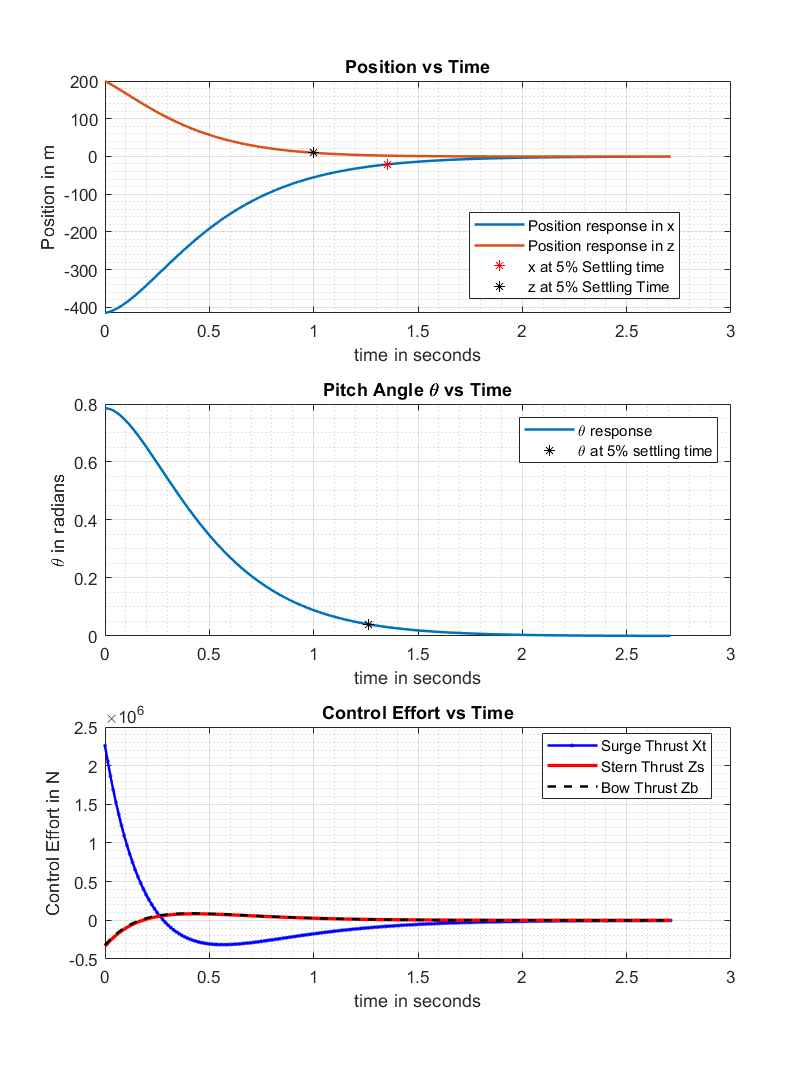

% We will construct the final Design plot. 
time = t6;
[~,index_output1] = min(abs(time - s(1).SettlingTime));
[~,index_output2] = min(abs(time - s(2).SettlingTime));
[~,index_output3] = min(abs(time - s(3).SettlingTime));
closed_loop_output = y6;
input = input6';


% Now we plot the graphs. The x and z have the same units and hence will be
% plot in the same graph. 
figure('Position',[10,10,900,1200])
subplot(3,1,1)

plot(time, closed_loop_output(:,1:2),'linewidth',1.5)
title('Position vs Time')
grid on
grid minor
hold on
plot(time(index_output1,1),closed_loop_output(index_output1,1),'r*')
hold on 
plot(time(index_output2,1),closed_loop_output(index_output2,2),'k*')
xlabel('time in seconds')
ylabel('Position in m')
leg=legend('Position response in x', 'Position response in z','x at 5% Settling time','z at 5% Settling Time');
set(leg,'location','best')

subplot(3,1,2)
plot(time, closed_loop_output(:,3),'linewidth',1.5)
hold on
grid on
grid minor
plot(time(index_output3,1),closed_loop_output(index_output3,3),'k*')
title('Pitch Angle \theta vs Time')
legend('\theta response','\theta at 5% settling time')
xlabel('time in seconds')
ylabel('\theta in radians')

subplot(3,1,3)
plot(time, input(:,1),'.-b','linewidth',1.5)
title('Control Effort vs Time')
grid on
grid minor
hold on
plot(time, input(:,2),'r','linewidth',2)
plot(time, input(:,3),'--k','linewidth',1.5)
xlabel('time in seconds')
ylabel('Control Effort in N')
leg=legend('Surge Thrust Xt', 'Stern Thrust Zs','Bow Thrust Zb');
set(leg,'location','best')

The Position are in the vehicle frame and not in the global frame. 

## Conclusion

Thus, a Closed-loop system has been generated by Iteratively calculating the Gain matrix by placing the poles such that the constraints of the design operation are satisfied. A stable system is thus generated while not undergoing control saturation.

## Final Project

r1 = 45;
r2 = 35;
r3 = 3;
% q/r = 1
% q1 = 40077500*r1;
% q2 = 400050000*r2;
% q3 = 900000000000*r3;
q1 = 60077500*r1;
q2 = 365550000*r2;
q3 = 9100000000000*r3;
Q = diag([0,q1,0,q2,0,q3])

Q = 	1.0e+13 *

         0         0         0         0         0         0
         0    0.0003         0         0         0         0
         0         0         0         0         0         0
         0         0         0    0.0013         0         0
         0         0         0         0         0         0
         0         0         0         0         0    2.7300




R = diag([r1,r2,r3])

R =     45     0     0
     0    35     0
     0     0     3



[K,S,P] = lqr(original_system,Q,R)

K = 	1.0e+06 *

    0.0027    0.0078    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0029    0.0183    0.0029    0.2548
   -0.0000   -0.0000    0.0030    0.0188   -0.0256   -2.8884


S = 	1.0e+11 *

    0.0006    0.0018    0.0000    0.0000   -0.0000   -0.0000
    0.0018    0.0099    0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0003    0.0019    0.0001    0.0010
    0.0000    0.0000    0.0019    0.0223    0.0005    0.0081
   -0.0000   -0.0000    0.0001    0.0005    0.0001    0.0116
   -0.0000   -0.0000    0.0010    0.0081    0.0116    2.4911


P = 	1.0e+02 *

  -0.0274 + 0.0274i
  -0.0274 - 0.0274i
  -0.0578 + 0.0574i
  -0.0578 - 0.0574i
  -1.0975 + 1.0975i
  -1.0975 - 1.0975i


## Check Animate



Ac = A_matrix - (B_matrix * K);
new_sys = ss(Ac,B_matrix,C_matrix,D_matrix);
[y6, t6, x6] = initial(new_sys,initial_condition_vector);
pos_x = y6(:,1)+465;
pos_z = y6(:,2)+150;
theta = y6(:,3);
input6 = -K*(x6');
maxinput1 = max(abs(input6(1,:))) *10/10;
maxinput2 = max(abs(input6(2,:))) *10/10;
maxinput3 = max(abs(input6(3,:))) *10/10;
table(maxinput1,maxinput2,maxinput3,'VariableNames',{'Max Control1', 'Max Control2','Max Control3'})

ans = 1×3 table
    Max Control1    Max Control2    Max Control3
    ____________    ____________    ____________

     2.9429e+06      2.9794e+06      2.6642e+06 


s = lsiminfo(y6,t6,'SettlingTimeThreshold',0.05);
settling_time(6,:) = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
table(output_names',settling_time(6,:)','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         0.73761    
    {'Position-y' }         0.33596    
    {'Pitch Angle'}        0.028527    


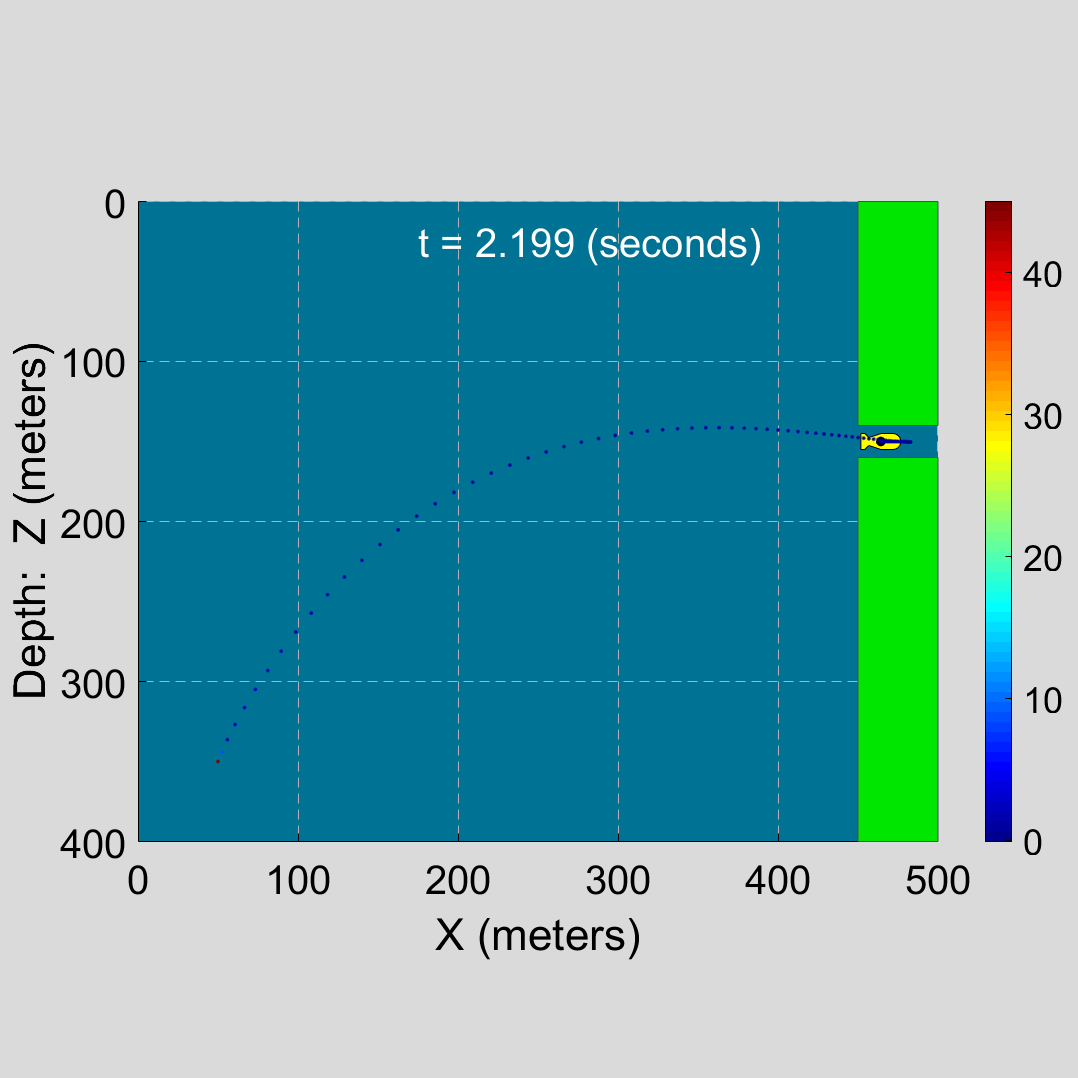

 animate_auv(t6,pos_x,pos_z,theta)